# Power Spectral Density Analysis

- Get the power spectral of each sample pair (i.e sick & normal)

- Sum the spectra of each class's (i.e sick & normal) channel across subjects. Also get the vector of the total power in all the channels (i.e sum all the channels)

- Plot the spectra of the relative power in each channel

- Plot the average power of each channel when summed across samples

- Plot average power of each class by using the previous results

For this code you need to change the directories of your trial to traget the right **dataset** and **sample extraction method**. In this case there are two datasets:-

- **Kfold_roi**: which includes ERP epoches

- **Kfold_pruned**: Epoches from continues EEG data

There are also two extraction methods:-

- Activation Maximization

- Sorting

# This is for sorted sample method

clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_pruned\trial 3\sorting\matrix_jitter_output.mat');
srate = 250;
nfft = srate;
f_length = (nfft/2) + 1;
sample_no = 29;
window_length = srate; % Size of the segments make to calculate PSD
overlap_length = 0; % Placing a 40% overlap between the segments
f = (0:1:40); % Frequencies of interest

% BEST SAMPLE VARIABLES 
t_s_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)
t_n_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)

% WORST SAMPLE VARIABLES
f_s_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)
f_n_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)

% ARRAY TO HOLD SAMPLES
true_sick_array = []; % 16x250xM here M is the number of samples 
true_normal_array = []; % 16x250xM here M is the number of samples 
false_sick_array = []; % 16x250xM here M is the number of samples 
false_normal_array = []; % 16x250xM here M is the number of samples 

for i = (1:sample_no)
    fieldName = ['field', num2str(i)];

    % GET THE SAMPLES
    % Get the best sick and normal samples
    true_sick_sample = export_matlab.(fieldName).true_sick;
    true_normal_sample = export_matlab.(fieldName).true_normal;

    % Get the worst sick and normal samples
    false_sick_sample = export_matlab.(fieldName).false_sick;
    false_normal_sample = export_matlab.(fieldName).false_normal;

    % GET THE SPECTRAS
    % Get the best spectra and their respective frequncies for both classes
    if ~isempty(true_sick_sample)
      if ~isempty(true_sick_array)
          true_sick_array = cat(3, true_sick_array, true_sick_sample);
      else
          true_sick_array = true_sick_sample;
      end
    end
    if ~isempty(true_normal_sample)
      if ~isempty(true_normal_array)
          true_normal_array = cat(3, true_normal_array, true_normal_sample);
      else
          true_normal_array = true_normal_sample;
      end
    end

    % Get the worst spectra and their respective frequncies for both classes
    if ~isempty(false_sick_sample)
      if ~isempty(false_sick_array)
          false_sick_array = cat(3, false_sick_array, false_sick_sample);
      else
          false_sick_array = false_sick_sample;
      end
    end
    if ~isempty(false_normal_sample)
      if ~isempty(false_normal_array)
          false_normal_array = cat(3, false_normal_array, false_normal_sample);
      else
          false_normal_array = false_normal_sample;
      end
    end

    % GET THE SUMMED SPECTRA
    % Sum the best output spectras of the subjects
%     t_s_sumed_spectra = t_s_sumed_spectra + t_s_spectra;
%     t_n_sumed_spectra = t_n_sumed_spectra + t_n_spectra; 
% 
%     % Sum the worst output spectras of the subjects
%     f_s_sumed_spectra = f_s_sumed_spectra + f_s_spectra;
%     f_n_sumed_spectra = f_n_sumed_spectra + f_n_spectra;

end

% GET THE SUMMED SPECTRA
% Sum the best output spectras of the subjects
for i = (1:size(true_sick_array, 3))
    [sp, fq] = pwelch(true_sick_array(:,:,i)', window_length, overlap_length, nfft, srate);
    t_s_sumed_spectra = t_s_sumed_spectra + sp';
end
for i = (1:size(true_normal_array, 3))
    [sp, fq] = pwelch(true_normal_array(:,:,i)', window_length, overlap_length, nfft, srate);
    t_n_sumed_spectra = t_n_sumed_spectra + sp';
end

% Sum the worst output spectras of the subjects
for i = (1:size(false_sick_array, 3))
    [sp, fq] = pwelch(false_sick_array(:,:,i)', window_length, overlap_length, nfft, srate);
    f_s_sumed_spectra = f_s_sumed_spectra + sp';
end
for i = (1:size(false_normal_array, 3))
    [sp, fq] = pwelch(false_normal_array(:,:,i)', window_length, overlap_length, nfft, srate);
    f_n_sumed_spectra = f_n_sumed_spectra + sp';
end


% GET THE RELATIVE POWER
% Best samples
t_s_summed_power = sum(t_s_sumed_spectra, 1); % The power of each frequency summed across channels
t_n_summed_power = sum(t_n_sumed_spectra, 1); % The power of each frequency summed across channels

t_s_relative_power = t_s_sumed_spectra ./t_s_summed_power; % The relative power of each channel compared to the total power
t_n_relative_power = t_n_sumed_spectra ./t_n_summed_power; % The relative power of each channel compared to the total power

% Worst samples
f_s_summed_power = sum(f_s_sumed_spectra, 1); % The power of each frequency summed across channels
f_n_summed_power = sum(f_n_sumed_spectra, 1); % The power of each frequency summed across channels

f_s_relative_power = f_s_sumed_spectra ./f_s_summed_power; % The relative power of each channel compared to the total power
f_n_relative_power = f_n_sumed_spectra ./f_n_summed_power; % The relative power of each channel compared to the total power

labels = {'MiPf', 'LLPf', 'RLPf', 'LMPf', 'RMPf', 'LMCe', 'RMCe', 'LDCe', 'RDCe', 'MiCe', 'MiPa', 'LDPa', 'RDPa', 'LMOc', 'RMOc', 'MiOc'};

## Plot Relative Power Density Of Each Channel

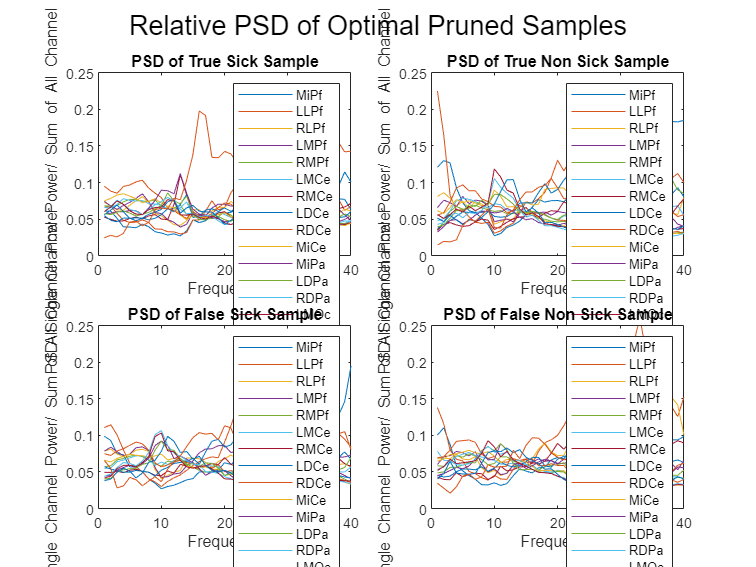

figure; % create a new figure

% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(t_s_relative_power, 1) % loop over rows
    plot(t_s_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Sick Sample');
ylabel('PSD {Single Channel Power/ Sum of All Channel Power}');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(t_n_relative_power, 1) % loop over rows
    plot(t_n_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Non Sick Sample');
ylabel('PSD {Single Channel Power/ Sum of All Channel Power}');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(f_s_relative_power, 1) % loop over rows
    plot(f_s_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Sick Sample');
ylabel('PSD {Single Channel Power/ Sum of All Channel Power}');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(f_n_relative_power, 1) % loop over rows
    plot(f_n_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Non Sick Sample');
ylabel('PSD {Single Channel Power/ Sum of All Channel Power}');
xlabel('Frequency');
ylim([0, 0.25]);
xlim([0, 40]);
legend(labels);

sgtitle('Relative PSD of Optimal Pruned Samples');

## Average Power Spectral Density of Each Channel

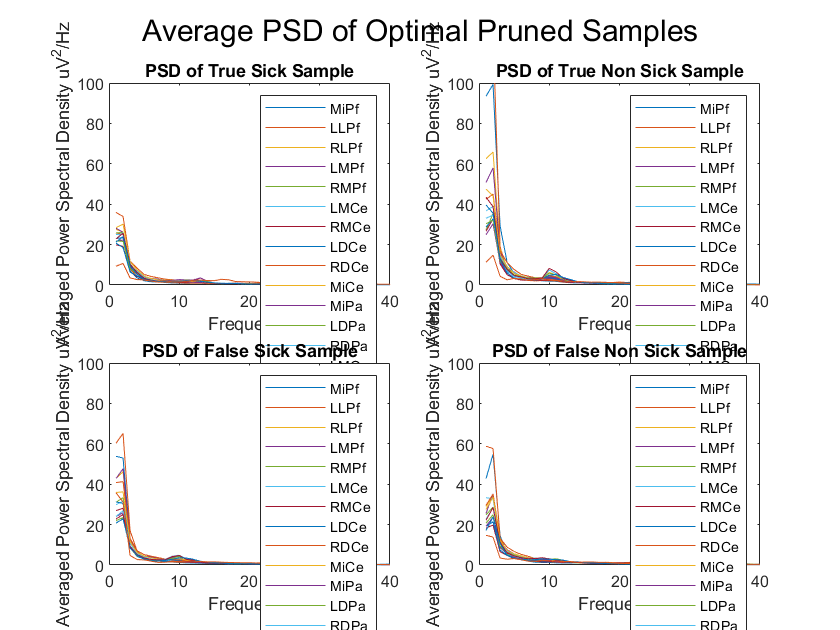

figure; % create a new figure

% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(t_s_sumed_spectra, 1) % loop over rows
    plot(t_s_sumed_spectra(i,:)/size(true_sick_array, 3)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Sick Sample');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 100]);
xlim([0, 40]);
legend(labels);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(t_n_sumed_spectra, 1) % loop over rows
    plot(t_n_sumed_spectra(i,:)/size(true_normal_array, 3)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of True Non Sick Sample');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 100]);
xlim([0, 40]);
legend(labels);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(f_s_sumed_spectra, 1) % loop over rows
    plot(f_s_sumed_spectra(i,:)/size(false_sick_array, 3)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Sick Sample');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 100]);
xlim([0, 40]);
legend(labels);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(f_n_sumed_spectra, 1) % loop over rows
    plot(f_n_sumed_spectra(i,:)/size(false_sick_array, 3)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of False Non Sick Sample');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
ylim([0, 100]);
xlim([0, 40]);
legend(labels);
sgtitle('Average PSD of Optimal Pruned Samples');

## Average Power Spectral Density of Summed Channel

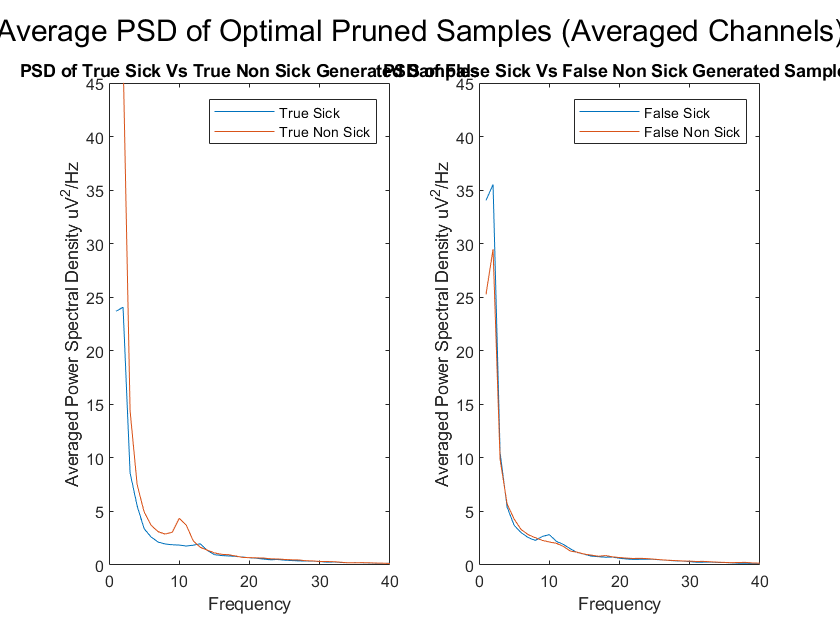

t_s_summed_channels_spectra = sum(t_s_sumed_spectra/size(true_sick_array, 3),1)/size(t_s_sumed_spectra,1); 
t_n_summed_channels_spectra = sum(t_n_sumed_spectra/size(true_normal_array, 3),1)/size(t_n_sumed_spectra,1); 

f_s_summed_channels_spectra = sum(f_s_sumed_spectra/size(false_sick_array, 3),1)/size(f_s_sumed_spectra,1); 
f_n_summed_channels_spectra = sum(f_n_sumed_spectra/size(false_normal_array, 3),1)/size(f_n_sumed_spectra,1); 

figure; % create a new figure

subplot(1,2,1);
plot(t_s_summed_channels_spectra);
hold on;
plot(t_n_summed_channels_spectra);
title('PSD of True Sick Vs True Non Sick Generated Samples');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
legend('True Sick', 'True Non Sick');
ylim([0, 45]);
xlim([0, 40]);

subplot(1,2,2);
plot(f_s_summed_channels_spectra);
hold on;
plot(f_n_summed_channels_spectra);
title('PSD of False Sick Vs False Non Sick Generated Samples');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
legend('False Sick', 'False Non Sick');
ylim([0, 45]);
xlim([0, 40]);
sgtitle('Average PSD of Optimal Pruned Samples (Averaged Channels)');

# This is for maximization activation method


clear;
load('C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_pruned\trial 3\maximization\matrix_jitter_output.mat');
srate = 250; % Sampling rate
nfft = srate;
f_length = (nfft/2) + 1;
sample_no = 29;
window_length = srate; % Size of the segments make to calculate PSD
overlap_length = 0; % Placing a 40% overlap between the segments
f = (0:1:40); % Frequencies of interest
s_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)
n_sumed_spectra = zeros(16, f_length); % The sum of the channel spectral subjects (16 X 126) => (Channels X Frequencies)

for i = (1:sample_no)
    fieldName = ['field', num2str(i)];

    % Get the sick and normal samples
    sick_sample = export_matlab.(fieldName).sick;
    normal_sample = export_matlab.(fieldName).normal;

    % Get the spectra and their respective frequncies for both classes
    [s_spectra, s_freqs] = pwelch(double(sick_sample'), window_length, overlap_length, nfft, srate);
    [n_spectra, n_freqs] = pwelch(double(normal_sample'), window_length, overlap_length, nfft, srate);
    % Sum the output spectras of the subjects
    s_sumed_spectra = s_sumed_spectra + s_spectra';
    n_sumed_spectra = n_sumed_spectra + n_spectra'; 
end

s_summed_power = sum(s_sumed_spectra, 1); % The power of each frequency summed across channels
n_summed_power = sum(n_sumed_spectra, 1); % The power of each frequency summed across channels

s_relative_power = s_sumed_spectra ./s_summed_power; % The relative power of each channel compared to the total power
n_relative_power = n_sumed_spectra ./n_summed_power; % The relative power of each channel compared to the total power

labels = {'MiPf', 'LLPf', 'RLPf', 'LMPf', 'RMPf', 'LMCe', 'RMCe', 'LDCe', 'RDCe', 'MiCe', 'MiPa', 'LDPa', 'RDPa', 'LMOc', 'RMOc', 'MiOc'};

## Plot Relative Power Density Of Each Channel

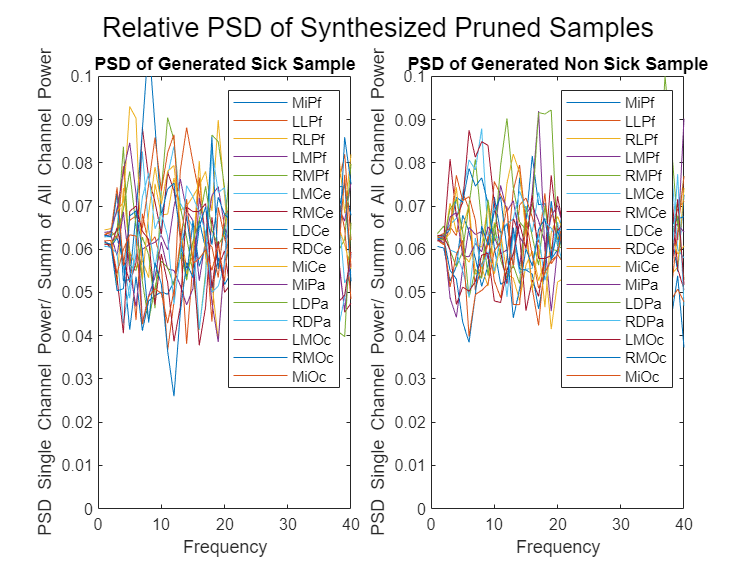

figure; % create a new figure

% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 2 columns, and select the first plot
for i = 1:size(s_relative_power, 1) % loop over rows
    plot(s_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Sick Sample');
ylabel('PSD {Single Channel Power/ Summ of All Channel Power}');
xlabel('Frequency');
ylim([0, 0.1]);
xlim([0, 40]);
legend(labels);

% Plot for matrix B
subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(n_relative_power, 1) % loop over rows
    plot(n_relative_power(i,:)); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Non Sick Sample');
ylabel('PSD {Single Channel Power/ Summ of All Channel Power}');
xlabel('Frequency');
ylim([0, 0.1]);
xlim([0, 40]);
legend(labels);
sgtitle('Relative PSD of Synthesized Pruned Samples');

## Average Power Spectral Density of Each Channel

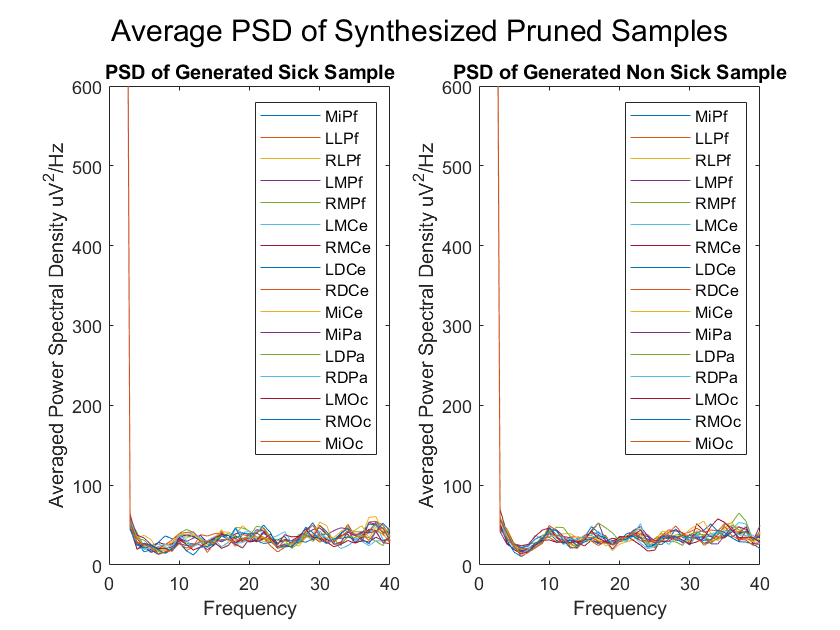

figure; % create a new figure

% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 2 columns, and select the first plot
for i = 1:size(s_sumed_spectra, 1) % loop over rows
    plot(s_sumed_spectra(i,:)/sample_no); % plot each row on the same plot. Divide by the number of samples to get the average
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Sick Sample');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
xlim([0, 40]);
ylim([0,600]);
legend(labels);

% Plot for matrix B
subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(n_sumed_spectra, 1) % loop over rows
    plot(n_sumed_spectra(i,:)/sample_no); % plot each row on the same plot. Divide by the number of samples to get the average
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Generated Non Sick Sample');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
xlim([0, 40]);
ylim([0,600]);
legend(labels);
sgtitle('Average PSD of Synthesized Pruned Samples');

## Average Power Spectral Density of Summed Channel

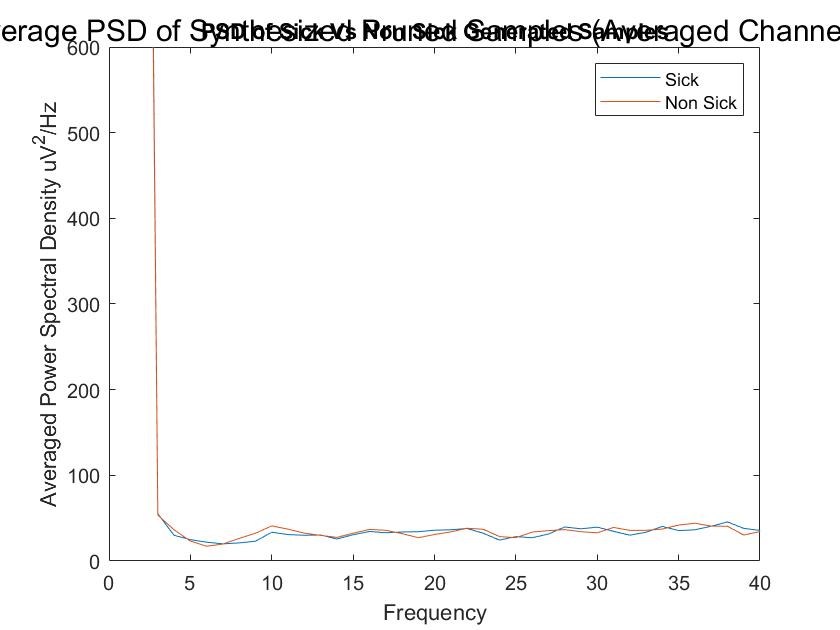

s_summed_channels_spectra = sum(s_sumed_spectra/sample_no,1)/size(s_sumed_spectra,1); 
n_summed_channels_spectra = sum(n_sumed_spectra/sample_no,1)/size(n_sumed_spectra,1); 

figure; % create a new figure
plot(s_summed_channels_spectra);
hold on;
plot(n_summed_channels_spectra);
title('PSD of Sick Vs Non Sick Generated Samples');
ylabel('Averaged Power Spectral Density uV^2/Hz');
xlabel('Frequency');
xlim([0, 40]);
ylim([0,600]);
legend('Sick', 'Non Sick'); % Add this line
sgtitle('Average PSD of Synthesized Pruned Samples (Averaged Channels)');